clear all, close all, clf
%Lab2 uppg 5
% Parametrar
% Vi vill hitta temperaturen i x = 1.65
a = 0;%start
L = 3.6;
T0 = 310;% T(0)
TL = 450;% T(L)
x_intr = 1.65;
options2 = odeset('RelTol', 1e-9);
options3 = odeset('RelTol', 1e-12);

%pga vi ej har Tprim måste vi gissa s (s_0) för att få fram derivatan til T
s_0 = [3;0];
function fel = inskjutning(s)
    % Parametrar
    a = 0;%start
    L = 3.6;
    T0 = 310;% T(0)
    TL = 450;% T(L)
    [~,Y] = ode45(@ekvationsys,[a,L],[T0,s]);
    fel = Y(end,1)-TL;
end
T_prim = fzero(@inskjutning, s_0(1));

[x,T] = ode45(@ekvationsys,[a,L],[T0,T_prim]);
[x2,T2] = ode45(@ekvationsys,[a,L],[T0,T_prim],options2);
[x3,T3] = ode45(@ekvationsys,[a,L],[T0,T_prim],options3);
%undersök
%hitta punker att interpolera
[~,intre1] = min(abs(x-1.65));%x=1.65
fprintf('Xindex=%.4f\n',intre1);

Xindex=19.0000


fprintf('j=%d x(j)=%.4f\n',intre1,x(intre1));

j=19 x(j)=1.6200


fprintf('j=%d x(j)=%.4f\n',intre1+1,x(intre1+1));

j=20 x(j)=1.7100


x(intre1-1:1:intre1+1)

ans =     1.5300
    1.6200
    1.7100


[~,intre2] = min(abs(x-2.96));%x=2.96
fprintf('Xindex=%.4f\n',intre2);

Xindex=34.0000


fprintf('j=%d x(j)=%.4f\n',intre2,x(intre2));

j=34 x(j)=2.9700


fprintf('j=%d x(j)=%.4f\n',intre2+1,x(intre2+1));

j=35 x(j)=3.0600


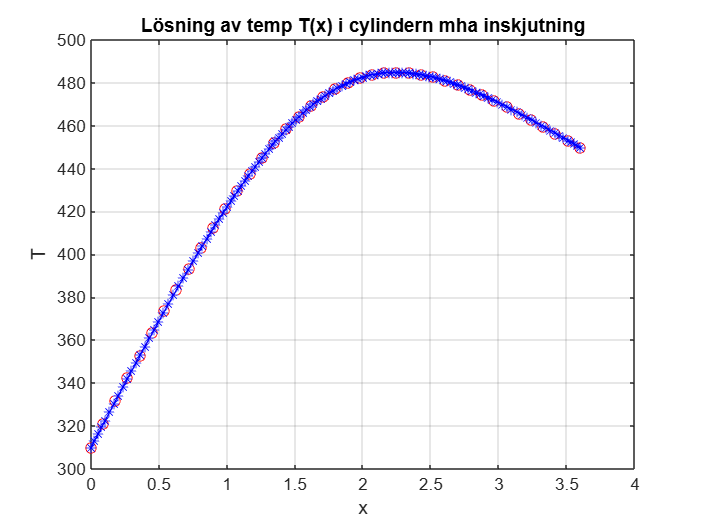

T_value1 = interp1(x,T(:,1),x_intr,'spline');
T_value2 = interp1(x2,T2(:,1),x_intr,'spline');
T_value3 = interp1(x3,T3(:,1),x_intr,'spline');
%T_value2 = interp1(x,T(:,1),x_intr,'cubic');
%funktion för lösning av diffekvation
function uprim = ekvationsys(x,u)
        %funktioner
        k=@(r) 3+r/7;
        L=3.6;
        Q=@(r) 280*exp(-(r-L/2)^2);
        %Diffekv-sys
        uprim(1) = u(2);
        uprim(2) = -Q(x)./k(x) -(1/(7*k(x))).*u(2);
        uprim=uprim';
end

plot(x, T(:,1), 'o-r');
xlabel('x');
ylabel('T');
hold on
plot(x2, T2(:,1), '*-b');
title('Lösning av temp T(x) i cylindern mha inskjutning');
grid on;

fprintf('T(1.65)=%.4f\n',T_value1);

T(1.65)=470.7569


fprintf('T(1.65)=%.4f\n',T_value2);

T(1.65)=470.7570


fprintf('T(1.65)=%.4f\n',T_value3);

T(1.65)=470.7570
